clear all
close all

addpath('../dasf_toolbox/');

Solve the the following spherically constrained quadratic problem (SCQP):


$$\text{arg}\min_X \frac{1}{2}\mathbb{E}[||X^T\mathbf{y}(t)||^2]+\text{tr}\left(X^TB\right)\\
\text{s.t. } \text{tr}\left(X^TX)=1,$$


in a distributed context using the Distributed Adaptive Signal Fusion (DASF) framework.

Let us first define the network. We take a randomly connected network with 30 nodes and 15 channels per node.

nbnodes=30;
nbsensors_vec=15*ones(nbnodes,1);
nbsensors=sum(nbsensors_vec);
adj=randi(2,nbnodes,nbnodes)-1;
graph_adj=triu(adj,1)+tril(adj',-1);
non_connected=find(all(graph_adj==0));
% If there are non-connected nodes, connect them to every other node.
if(non_connected)
    graph_adj(:,non_connected)=1;
    graph_adj(non_connected,:)=1;
end

Next, we create the data using 

found at the end of this file. The number of time samples of the signals is 10000 and we choose the number of filters to be equal to 3, i.e., $X$ has 3 columns.

nbsamples=10000;
Q=3;
[Y,B]=create_data(nbsensors,nbsensors_vec,nbnodes,nbsamples,Q);

The data are stored in 4 different cells, 

- One for the (stochastic) signals. In this example, the cell contains only one element, the signal $\mathbf{y}$. 

Y_cell{1}=Y;

- One for deterministic constant matrices. In this example, we have $B$.

B_cell{1}=B;

- One for quadratic terms. Here, we have only one, which is the identity matrix.

Gamma_cell{1}=eye(nbsensors);

- The final one for global constraint parameters, i.e., those that are not filtered using $X$. In this case, we do not have any.

Glob_Const_cell={};

We then create structures for the data, problem parameters and stopping criteria called 

respectively:

data=struct;
data.Y_cell=Y_cell;
data.B_cell=B_cell;
data.Gamma_cell=Gamma_cell;
data.Glob_Const_cell=Glob_Const_cell;

prob_params=struct;
prob_params.nbsensors=nbsensors;
prob_params.Q=Q;
prob_params.nbnodes=nbnodes;
prob_params.nbsensors_vec=nbsensors_vec;
prob_params.nbsamples=nbsamples;
prob_params.graph_adj=graph_adj;

We fix the number of iterations the DASF algorithm will perform to 200.

conv=struct;
conv.nbiter=200;

We choose a randomly selected updating order for the distributed implementation:

prob_params.update_path=randperm(nbnodes);
prob_params.update_path

ans =     20    23    19     7    14    17     5    30    24    10    13     1    15    12    27     4    28     6     8    16     3    26    21    11    29    22     9    25    18     2


Then, an optimal filter $X^*$ solving the SCQP is estimated using the centralized algorithm: 

[X_star,f_star]=scqp_solver(prob_params,data);
prob_params.X_star=X_star;
% Compute the distance to X^* if "true".
prob_params.compare_opt=true;
% Show a dynamic plot if "true".
prob_params.plot_dynamic=false;

The distributed implementation is then called using the function 

 which takes as parameters the data, problem parameter and stopping criteria structures along with the functions 

which evaluates the SCQP objective given a certain $X$ and solves the centralized SCQP, respectively. In this example, we do not require a function which resolves the uniqueness ambiguity of the problem since there is a unique $X$ solving the problem, which is why we leave its argument slot empty.

[X_est,norm_diff,norm_err,f_seq]=dasf(prob_params,data,...
                    @scqp_solver,conv,[],@scqp_eval);

Let us plot the normalized error $\epsilon$ given by:

$\epsilon(X^i)=\frac{||X^i-X^*||_F^2}{||X^*||_F^2}$,

which is stored in

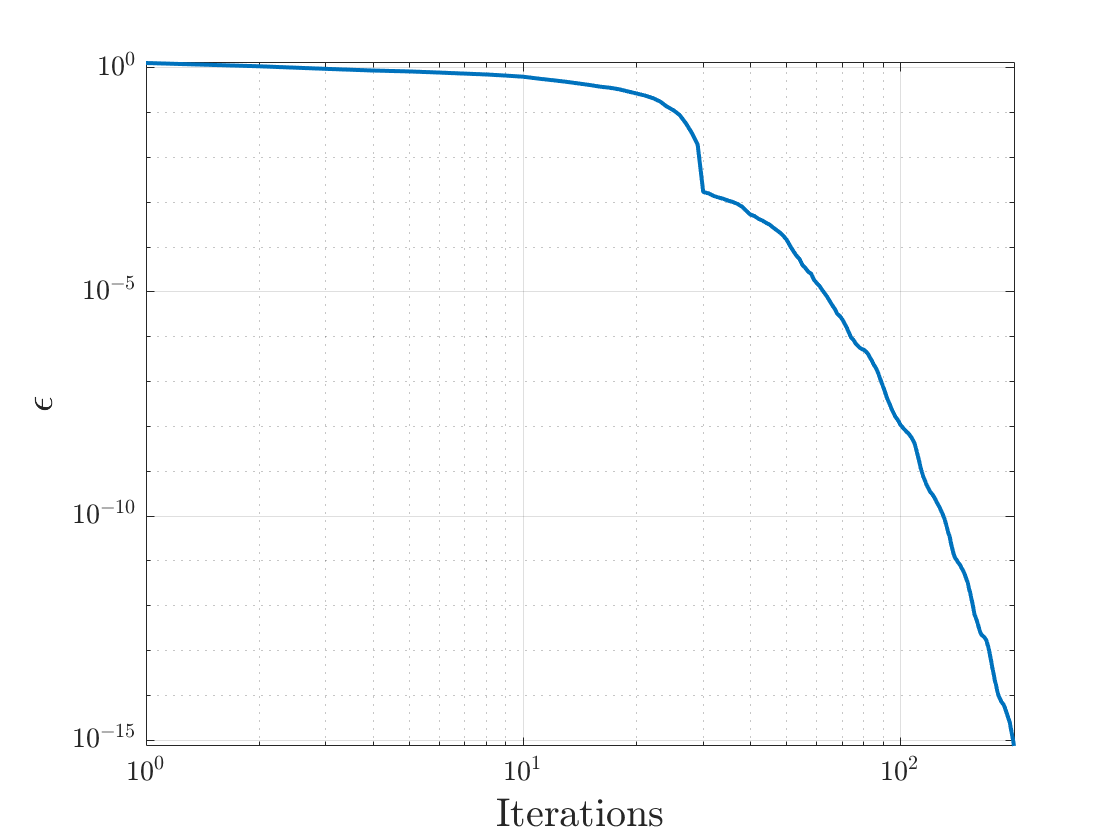

loglog([1:200],norm_err,'LineWidth',2)
ax=gca;
ax.FontSize=14;
xlabel('Iterations','Interpreter','latex','Fontsize',20)
ylabel('$\epsilon$','Interpreter','latex','Fontsize',20)
xlim([1,inf])
grid on

Fuctions used to create the data..

function [Y,B]=create_data(nbsensors,nbsensors_vec,nbnodes,nbsamples,Q)
   
    signalvar=0.5;
    noisepower=0.1;
    nbsources=10;
    offset=0.5;
    
    rng('shuffle');
    S=randn(nbsources,nbsamples);
    S=sqrt(signalvar)./(sqrt(var(S,0,2))).*(S-mean(S,2)*ones(1,nbsamples));

    for k=1:nbnodes
        A{k}=rand(nbsensors_vec(k),nbsources)-offset;
        noise{k}=randn(nbsensors_vec(k),nbsamples); 
        noise{k}=sqrt(noisepower)./sqrt(var(noise{k},0,2)).*(noise{k}...
            -mean(noise{k},2)*ones(1,nbsamples));
    end

    teller=0;

    for k=1:nbnodes
        Y_cell{k}=A{k}*S+noise{k};
        Y(teller+1:teller+nbsensors_vec(k),1:nbsamples)=Y_cell{k};
        teller=teller+nbsensors_vec(k);
    end
    
    B=randn(nbsensors,Q);

end